# MATLAB Companion Script (1 of 2) for *Machine Learning* ex8 (Optional)

## Introduction

Coursera's* Machine Learning* was designed to provide you with a greater understanding of machine learning algorithms- what they are, how they work, and where to apply them. You are also shown techniques to improve their performance and to address common issues. As is mentioned in the course, there are many tools available that allow you to use machine learning algorithms *without* having to implement them yourself. This Live Script was created by MathWorks to help *Machine Learning* students explore the data analysis and machine learning tools available in MATLAB.

## FAQ

**Who is this intended for?**

- This script is intended for students using MATLAB Online who have completed ex8 and want to learn more about the corresponding machine learning tools in MATLAB.

**How do I use this script?**

- In the sections that follow, read the information provided about the data analysis and machine learning tools in MATLAB, then run the code in each section and examine the results. You may also be presented with instructions for using a MATLAB machine learning app. This script should be located in the ex8 folder which should be set as your Current Folder in MATLAB Online.

**Can I use the tools in this companion script to complete the programming exercises?**

- No. Most algorithm steps implemented in the programming exercises are handled automatically by MATLAB machine learning functions. Additionally, the results will be similar, but not identical, to those in the programming exercises due to differences in implementation, parameter settings, and randomization.

**Where can I obtain help with this script or report issues?**

-  As this script is not part of the original course materials, please direct any questions, comments, or issues to the *MATLAB Help* discussion forum.

# Anomaly Detection

In the first part of this Live Script, we will use tools from the [Statistics and Machine Learning Toolbox](https://www.mathworks.com/products/statistics.html) to implement an anomaly detection system. We then discuss methods for fitting statistical distributions to measured data, as well as adjusting and evaluating the performance of our detector. 

## Files needed for this script

- `ex8data1.mat` - First example dataset for anomaly detection

- `ex8data2.mat` - Second example dataset for anomaly detection

# Data Visualization and Probability Distribution Fitting

In this section we visualize the sever data from ex8 using scatter plots and histograms before fitting a distribution to the data using functions and apps from the Statistics and Machine Learning Toolbox. 

## Load the data

Recall that the data used in the first part of ex8 consisted of two features: measurements of the throughput (mb/s) and latency (ms) each server as well as a separate set validation measurements and labels that denoted anomalous behavior. Run the code in this section to load the variables `X`, `Xval` and `yval` into the workspace and create a `table` for the validation data and labels, then compute some summary statistics on the validation data. Recall that 0's denote normal behavior and 1's denote anomalous behavior.

clear;
load('ex8data1.mat');
dataval = table(Xval(:,1),Xval(:,2),yval==1,'VariableNames',{'Throughput','Latency','Anomaly'});
summary(dataval)

Variables:

    Throughput: 307×1 double

        Values:

            Min       0.30794 
            Median     14.031 
            Max        28.542 

    Latency: 307×1 double

        Values:

            Min        5.3914 
            Median     15.021 
            Max        23.356 

    Anomaly: 307×1 logical

        Values:

            True         9   
            False      298   



## Visualize the data using `scatterhist` 

Before fitting a distribution to data, it's helpful to visualize the data to see what existing probability distributions might make for a reasonable fit. Run the code below to see how the values of the normal and anomalous data is distributed across the two variable values using the [`scatterhist`](https://www.mathworks.com/help/stats/scatterhist.html) function.

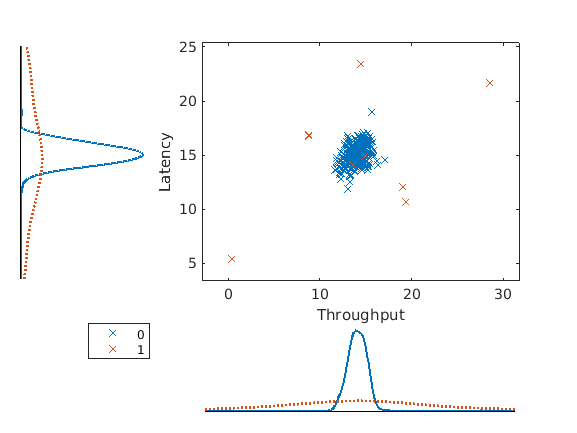

scatterhist(dataval.Throughput,dataval.Latency,'Group',dataval.Anomaly,'Kernel','on','Marker','x')
xlabel('Throughput');
ylabel('Latency');

From the resulting plot, the 'normal behavior' observations appears approximately normally distributed with most observations concentrated symmetricaly about the mean. The 'anomalous behavior' observations appear more evenly distributed over the range of variable values and also appear symmetrically distributed about the overall means, however there are considerably fewer anomalous observations.

## Visualize distribution fits using `histfit`

Below we provide code to visualize potential distribution fits using the [`histfit`](https://www.mathworks.com/help/stats/histfit.html) function, which plots a histogram of the data and the fitted distribution. Run the code to plot two potential distribution fits for each variable, the normal and t-distributions, for comparison.

f = figure;
subplot(2,2,1);
histfit(dataval.Throughput,25,'normal');
title('Normal distribution fit')
xlabel('Throughput');
axis square
subplot(2,2,2); 
histfit(dataval.Throughput,25,'tlocationscale');
title('t-distribution fit')
xlabel('Throughput');
subplot(2,2,3);
histfit(dataval.Latency,25,'normal');
title('Normal distribution fit')
xlabel('Latency');
axis square
subplot(2,2,4); 
histfit(dataval.Latency,25,'tlocationscale');
title('t-distribution fit')
xlabel('Latency');
set([f.Children.YLabel],'String','Count')
axis square

While the t-distribution appears to offer better fit to the data based on the above plots, the normal distribution is still a reasonable choice and offers easier comparison with the results from ex8, so we will use that distribution in the next few sections. 

## Fit a probability distribution to data using `fitdist`

To fit a distribution to each variable, we will use the [`fitdist`](https://www.mathworks.com/help/stats/fitdist.html) function, which takes a data vector and distribution name as input, and returns the fitted distribution parameters as output. The number and meaning of the parameters vary by distribution- see the [documentation](https://www.mathworks.com/help/stats/fitdist.html#btu538h-distname) for more details and available distributions. Run the code below to fit a normal distribution to the Throughput data (we fit a normal distribution to the Latency data in the next section). The `fitdist` function will return a `NormalDistribution` variable that contains the parameters as well as additional fit information including the confidence bounds for each parameter. We then extract the parameters into the first elements of the variables `mu` and `sigma` respectively. 

mu = zeros(1,2);
sigma = mu;
distMdl1 = fitdist(dataval.Throughput,'Normal')

distMdl1 =   NormalDistribution

  Normal distribution
       mu = 14.0193   [13.8408, 14.1978]
    sigma = 1.58937   [1.47281, 1.72612]


mu(1) = distMdl1.mu;
sigma(1) = distMdl1.sigma;

**Note: **If you have difficulty reading the instructions below while the app is open in MATLAB Online, export this script to a pdf file which you can then use to display the instructions in a separate browser tab or window. To export this script, click on the 'Save' button in the 'Live Editor' tab above, then select 'Export to PDF'.

## Fit a probability distribution to data using the Distribution Fitter App

In the next few sections we provide instructions for fitting a normal distribution to the latency data using the[ Distribution Fitter App](https://www.mathworks.com/help/stats/model-data-using-the-distribution-fitting-tool.html) and export/extract the model parameters:

- In the '**Apps**' tab,  expand the list of apps and select '**Distribution Fitter**' from the '**Math, Statistics, and Optimization**' group.

- Click on the '**Data**' button.

- Expand the '**Data**' drop-down menu under '**Import workspace vectors'** and select '**Xval**'.

- Click on the '**Select Column or Row**' button. In the box that appears, click on the '**2**' at the top of the second column to select the entire column, then click '**OK**'.

- Click on the '**Create Data Set**' button, then click '**Close**'.

## Fit a normal distribution and export the `NormalDistribution` variable to the workspace

- In the Distribution Fitter window, click on the '**'New Fit**' button

- In the '**New Fit**' window, confirm that the second column of `Xval` is selected in '**Data**', and '**Normal**' is selected in **'Distribution**'.

- Click the '**Apply**' button.

- Click on the '**Save to Workspace**' button. 

- In the '**Save fitted distribution as:**' box that appears, enter '**distMdl2**' then click '**Ok**'

- Close the '**Edit** **Fit**' menu (the 'New Fit' menu becomes the 'Edit Fit' menu once a distribution is fitted).

## Evaluate the fit and extract the parameters

- In the plot shown, compare the fitted PDF with the histogram. 

- The default plot view is 'Density Plot'. To further examine the fit, select one of the additional plot views in the '**Display Type**' drop-down menu.

- When you are finished, close the Distribution Fitter App (there is no need to save the current session).

- Run the code below to extract the values of $\mu$ and $\sigma$ from the exported distribution variable into the second elements of the `mu` and `sigma` vectors created earlier.

mu(2) = distMdl2.mu;

Unable to resolve the name distMdl2.mu.

sigma(2) = distMdl2.sigma;

## Obtain the multivariate normal PDF values using `mvnpdf` 

Now that we have fitted the probability distribution model coefficients, we'll create a contour plot of the probability distribution as in ex8. Run the code below to plot the observations and probability contours using the local function `probContour` defined at the end of this script. This function uses the [`mvnpdf`](https://www.mathworks.com/help/stats/mvnpdf.html) function and the normal distribution parameters fitted previously to calculate the multivariate probability values for a grid of throughput and latency values.

probContour(dataval,mu,sigma);

# Model Assessment and Cutoff Parameter Selection

After obtaining the distribution parameters, the next step in implementing the anomaly detection model is to select a cutoff parameter for flagging anomalies using the labeled validation data. In this section we use tools including the confusion matrix and performance curves for visualizing and evaluating model performance for various choices of this parameter, then we provide a method for obtaining this value automatically using the `perfcurve` function.

## Obtain the confusion matrix and calculate the $F_1$ score

In ex8 you used the validation set to select a probability cutoff parameter $\epsilon$ for anomaly prediction corresponding to the best $F_1$ score. Recall that the $F_1$ score depends on the *precision* and *recall* values, which in turn depend on the true positive, false positive, and false negative counts denoted $t_p$, $f_p$, and $f_n$ respectively.  We obtain these values in MATLAB by generating a *confusion matrix* using the [`confusionmat`](https://www.mathworks.com/help/stats/confusionmat.html) function. The confusion matrix for a binary classifier is a 2x2 matrix whose elements are comprised of the three counts above, along with the true negative rate $t_n$, organized as follows:


$$C = \left(\begin{array}{cc} t_p & f_n \\ f_p & t_n\end{array}\right)$$


In general, the confusion matrix for an $n$-class classifier is organized such that $C_{ij}$ corresponds to the number of elements *classified* as class $i$ whose *true class* is $j$. Better model performance is therefore indicated by higher counts on the diagonal vs. off-diagonal. The off-diagonal (incorrectly classified) elements of a confusion matrix indicate how predictive errors are distributed among the classes and error types.

    Use the control below to select a cuttoff value $\epsilon$ from a vector of 15 logarithmically-spaced values from $10^{-8}$ to $10^{-2}$. The code will then compute and print the precision, recall, and $F_1$ values for a given choice of $\epsilon$. What value(s) produce the best results as judged by the fewest misclassified points? What about when judging by the precision, recall, and $F_1$ score? The data and probability contours are also plotted for you to explore how the cuttoff value affects these values. 

epsilon = 1e-4;
% Compute the probability contours
Xvalprobs = mvnpdf(Xval,mu,sigma.^2);
yvalpred = Xvalprobs < epsilon;
confmat = confusionmat(yvalpred,dataval.Anomaly)
precision = confmat(2,2)/(confmat(2,2)+confmat(1,2));
recall = confmat(2,2)/(confmat(2,2)+confmat(2,1)); 
F1 = 2*precision*recall/(precision+recall);
fprintf('Epsilon: %g | Precision: %g | Recall: %g | F1: %g',epsilon, precision,recall,F1);
% Probability contour plot
[Xplot,Yplot,Zplot] = probContour(dataval,mu,sigma); hold on;
contour(Xplot,Yplot,Zplot,[epsilon epsilon],'r');
errinds = yvalpred ~= yval;
plot(dataval.Throughput(errinds),dataval.Latency(errinds),'mo','MarkerSize',10); 
hold off;
legend({'Probability contours','Normal behavior','Anomalous behavior','Cuttoff contour',...
        'Misclassified points'},'Location','northeast');  

If you searched through all of the $\epsilon$ values above, you found that the fewest number of misclassified points is 3, and the precision, recall, and $F_1$ scores peak between $\epsilon = 10^{-4}$ and $10^{-3}$. However, if you look closely there appears to be an optimal $\epsilon$ between these two values such that only two points will be misclassified. In the next section we discuss a method for finding this optimal value for a given performance metric.

## Determine the optimal cuttoff value using performance curves

The $F_1$ statistic provides a good assessment of model performance in cases like the anomaly detection example, where the validation data is heavily skewed towards true negative examples which aren't included in the $F_1$ computation- otherwise a model that classifies all values as negative would be judged as 'good'. A more general alternative to the $F_1$ score is found by using [performance curves](https://www.mathworks.com/help/stats/performance-curves.html) to select cutoff values. The idea behind performance curves is as follows: for a set of probability scores $S$ obtained from a machine learning  model and a (sequential) set of probability cuttoff values $\epsilon_i$, plot the values of the *performance statistics*, $p_i^{1}$ and $p_{i}^2}$. This plot called a performance curve and it provides a visual means to track the performance of a classifier as judged by the given metrics as the cutoff is varied. The most common performance statistics are the false positive rate and true positive rates. A performance curve generated using these two statistics is commonly known as a [Receiver Operating Characteristic](https://en.wikipedia.org/wiki/Receiver_operating_characteristic) (ROC) curve. The point on the curve representing the ideal 'balance' between the two statistics (and thus the classifier best model) is referred to as the *optimal operating point*- see the [`perfcurve`](https://www.mathworks.com/help/stats/perfcurve.html) documentation for more on how this point is determined.

    Run the code below to compute the ROC curve and the optimal operating point for the current probability model using the `perfcurve` function, which returns the performance statistic values, the corresponding threshold values, and the cuttoff value corresponding to the optimal operating point. This value is determined with the assumption that the 'cost' for the two performance statistics (true and false positive rates for ROC curves) is equal, but that need not be the case in general. For example, false positives could be considered more 'costly' than false negatives in certain models and thus weights can be added to reflect this, or alternatively other performance statistics chosen by providing `perfcurve` with additional inputs- see the documentation for more details. 

[Xroc,Yroc,T,auc,Opt] = perfcurve(yval,Xvalprobs,0);
Topt = T(Opt(1) == Xroc & Opt(2) == Yroc);
fprintf('Best epsilon found using ROC performance curve: %g',Topt)
plot(Xroc,Yroc); hold on;
plot(Opt(1),Opt(2),'ro'); 
hold off; axis square;
xlabel('False positive rate (1-specificity)');
ylabel('True positive rate (sensitivity)');
title('ROC curve')

**Implementation Note:** By default, a probability score greater than the cutoff corresponds to a 'positive' classification (i.e. y == 1), but in our anomaly detection model the opposite is true, therefore we added an additional input to `perfcurve` to associate the 'positive' class with those observations such that `yval(i)==0`.

## Compare model performance using ROC curves

In addition to helping evaluate potential cutoff values, ROC curves also offer a visual means for comparing the performance of two different classifier models. The main idea is that if one performance curve lies above another over a majority of the threshold values, the corresponding model is more robust. For a more quantitative comparison, the total area under the ROC curves is used to compare between models. As an example, recall that by calculating the variance of the two feature variables separately in our current model, we have implicitly assumed that these variables are independently distributed (corresponding to a diagonal covariance matrix). In the code below, we calculate the full covariance matrix for the multivariate normal distribution and use it as part of an alternative probability model. The ROC curves and areas under the curves are then used to compute the optimal cutoff values for each model and to compare their performance.

% Replot existing ROC curve
plot(Xroc,Yroc,'b'); hold on;
plot(Opt(1),Opt(2),'bo'); 
xlabel('False positive rate (1-specificity)');
ylabel('True positive rate (sensitivity)');
title('ROC curve');

% Compute and plot the full covariance model ROC curve
Xvalprobs2 = mvnpdf(Xval,mu,cov(Xval));
[Xroc2,Yroc2,T2,auc2,Opt2] = perfcurve(yval,Xvalprobs2,0);
Topt2 = T2(Opt2(1) == Xroc2 & Opt2(2) == Yroc2);
fprintf('Best epsilon for full covariance model found: %g',Topt2)
plot(Xroc2,Yroc2,'r');
plot(Opt2(1),Opt2(2),'rx'); hold off;
legend({'Independent','Optimal Point','Full','Optimal Point'}, 'Location','NorthEast')
fprintf('Independent variable AUC: %g | Full covariance AUC: %g', auc,auc2);

From the plot above, we can see that the performance of the two models is generally comparable, and in fact both produce the same performance statistic values as the optimal operating point (though the corresponding threshold values are slightly different). The areas under the ROC curves are also comparable, which implies that their performance is generally equal and there is not much to be gained from including the full covariance matrix in our model.

## Fit a multivariate probability model to the high dimensional dataset

In this section we use the tools from the previous sections to create an anomaly detection algorithm for the full dataset with 11 features. Run the code below to load the data. calculate the model parameters, and obtain the optimal cutoff value using the ROC curve. The model is then used to predict the number of outliers in the non-validation set- compare with your results from ex8.

clear;
load('ex8data2.mat');
mu = mean(Xval);
sigma2 = cov(Xval);
Xvalprobs = mvnpdf(Xval,mu,sigma2);
[Xroc,Yroc,T,auc,Opt] = perfcurve(yval,Xvalprobs,0);
Topt = T(Opt(1) == Xroc & Opt(2) == Yroc);
fprintf('Best epsilon found using ROC: %e\n', Topt);
confusionmat(Xvalprobs < Topt,yval==1)
plot(Xroc,Yroc); hold on;
plot(Opt(1),Opt(2),'bx'); hold off;
xlabel('False positive rate (1-specificity)');
ylabel('True positive rate (sensitivity)');
title('ROC curve'); 
fprintf('# of outliers predicted: %d',sum(mvnpdf(X,mu,sigma2) < Topt));

# Local Functions

## `probContour`

`propContour` plots the probability contours for a normal distribution and the Throughput-Latency validation dataset provided as a `table` input. The variable means and standard deviations are also provided as input to compute the normal PDF values from the fitted distribution for a grid of feature values.

function [Xplot,Yplot,Zplot] = probContour(dataval,mu,sigma)
    % Compute probability grid
    [Xplot,Yplot] = meshgrid(linspace(min(dataval.Throughput),max(dataval.Throughput),200),...
                             linspace(min(dataval.Latency),max(dataval.Latency)),200);
    Zplot = mvnpdf([Xplot(:),Yplot(:)],mu,diag(sigma).^2);
    Zplot = reshape(Zplot,size(Xplot));
    % Plot probability contours
    figure; hold on;
    contour(Xplot,Yplot,Zplot,10.^(-20:4:0),'showtext','on','Color','k');
    plot(dataval.Throughput(~dataval.Anomaly),dataval.Latency(~dataval.Anomaly),'bx');
    plot(dataval.Throughput(dataval.Anomaly),dataval.Latency(dataval.Anomaly),'rx');
    title('Probability Density Contours');
    ylabel('Latency (ms)'); 
    xlabel('Throughput (mb/s)'); 
    hold off;
end